PHYSICS 434 

Author: Avi Soval

Collaborators: Jeff Jiang, Thomas Conaway 

11.17.19

## Lab 6: Confidence Intervals 

**In this lab, we explore the relationship between observed and true signals measured against a simulated background data distribution. Since our 'observed' signals are the result of a suite of signals injected onto a background noise distribution, we can expect the histograms of our collection of data to change depending on the signals we inject. **

#### **Problem I**

**We begin by creating a simulated Poisson background distribution with a mean of 100. The x-axis for this lab refers to the 'signal strength', but this number is arbitrary and does not have a physical quantity attached to it. A higher signal strength would correspond to a theoretically higher signal. We then calculate the 5-sigma value for a signal strength measured against this background. **

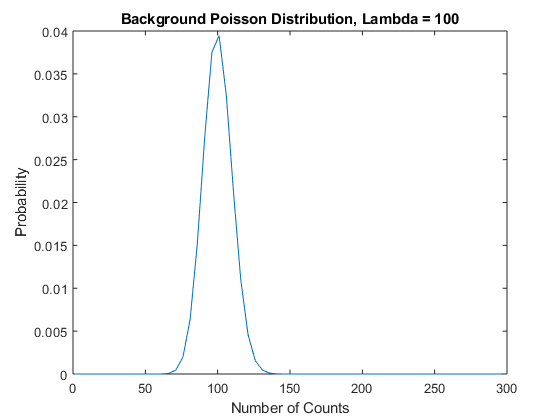

background = makedist('Poisson','lambda',100); 
x = 1:5:300; 
bg = pdf(background,x); 

figure(1)
plot(x,bg); 
xlabel('Number of Counts'); 
ylabel('Probability'); 
title('Background Poisson Distribution, Lambda = 100'); 


thresh = 3.5e-6; 
y = icdf(background,1-thresh); 
disp("The 5-sigma value for a detection in this background is " + y)

The 5-sigma value for a detection in this background is 148


#### Problem II 

**Now, we will inject a set of simulated signals into this background, with all of the injected signals of the same strength. Injecting the signal into the background means that the signal is simply added to the background signal strength an arbitrary number of times. We first create a dataset from the Poisson background pdf, and plot a histogram of this distribution below. **

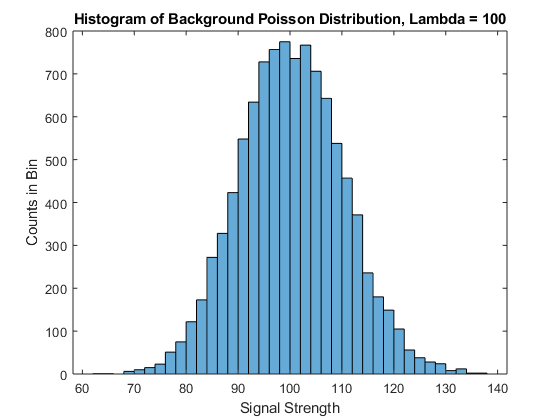

background = poissrnd(100,[10000 1]); 

figure(2)
histogram(background); 
xlabel('Signal Strength'); 
ylabel('Counts in Bin'); 
title('Histogram of Background Poisson Distribution, Lambda = 100'); 

**We now inject a simulated signal of strength 200 into this distribution an N number of times, determined by the 'signal_count' control bar directly below. **

signal_strength = 200; 
signal_count = 500;

data = background; 

ix = randi(length(data),signal_count,1); 

for i = 1:length(ix)
    
    data(ix(i)) = data(ix(i)) + signal_strength; 
    
end

**The histogram of this new distribution with all the injected data is shown here. **

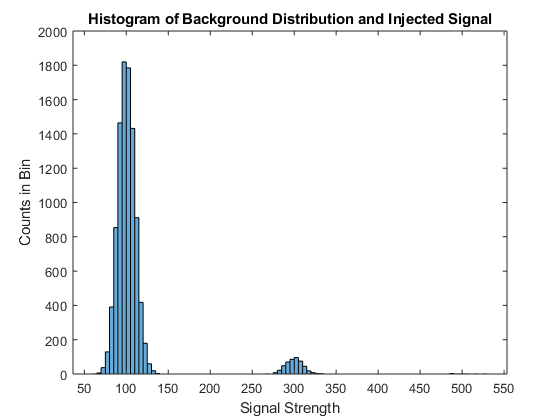

figure(3)
histogram(data); 
xlabel('Signal Strength'); 
ylabel('Counts in Bin'); 
title('Histogram of Background Distribution and Injected Signal'); 

**As we expect, a set of datapoints the size of the 'signal_counts' variable has been shifted upwards by the signal strength of 200, and produces a secondary region on the histogram. In this new plot, the second hill is comprised purely of observed signals, which is the sum of the background and our injected signal. The brightness, or size of the observed signal, is dependent on the number of times the signal is injected into the background. Clearly, the observed signal is symmetrically biased - since it is the sum of the background and the true (injected) signal, the observed signal will *****always *****be stronger than the true signal. The fact that the true signal is injected randomly into the original background distribution also accounts for the symmetric distribution of the observed data. **

**Problem III **

**Now, we will produce a suite of injected signals that occupy a range of potential signal strengths. We set this range to be a strength of 0 - 500, with a maximum strength of 500 corresponding to roughly a 30-sigma measurement against the poisson background. The objective here will be to plot the behavior of the observed signal over this range of injected signal strengths. Since we are analyzing the behavior of the observed signal only, we omit the remainder of the background data and plot only the indices of the background that have had the true signal injected into them. Thus, we can create a 2D histogram of the observed vs. injected signal, as shown below. **

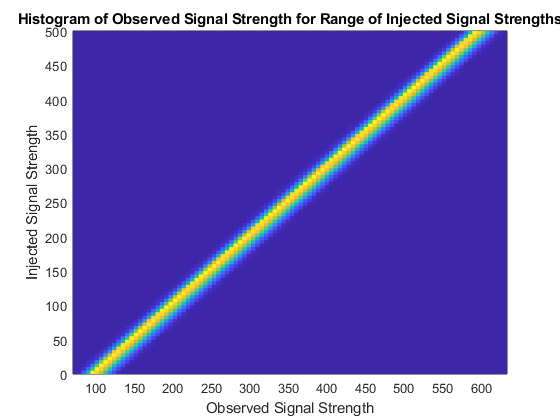

signal_strengths = linspace(0,500,10000); 
injected_data = zeros(10000); 
all_injected_data = injected_data;
num_signals = 500; 
ix = randi(10000,num_signals,1); 

for i = 1:10000
    
    all_injected_data(i,:) = background; % all_injected_data has both the background Poisson and the injected signals on top of it 
    all_injected_data(i,ix) = background(ix) + signal_strengths(i);
    injected_data(i,ix) = background(ix) + signal_strengths(i); % injected_data only has the observed signals, with all other background entries as 0 

end

figure(4)
injected_data(injected_data==0) = nan; 
[scratch, signal] = meshgrid(signal_strengths); 
histogram2(injected_data,signal,100,'DisplayStyle','tile','ShowEmptyBins','on'); 
xlabel('Observed Signal Strength'); 
ylabel('Injected Signal Strength'); 
title('Histogram of Observed Signal Strength for Range of Injected Signal Strengths'); 

**In this 2D histogram, the range of injected signal strengths are plotted on the y-axis. Each increment along this injected signal strength line corresponds to a unique 1D histogram of the observed signal only data that resulted from this strength of injected signal. As we can see, the observed signal strength increases linearly with the strength of the injected signal data. Additionally, along the line apparent in the 2D histogram, each observed signal datapoint is offset by roughly 100 from the injected signal that produced it, which makes sense considering the average strength of the background was 100. **

**We can extract the histogram that corresponds to an injected signal strength of 200 and compare it to the plot produced in Problem II. **

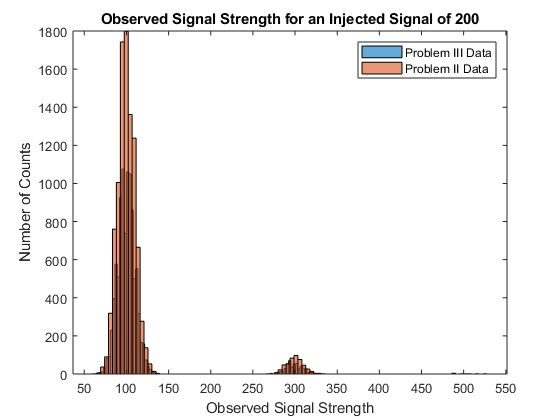

figure(5)
histogram(all_injected_data(4000,:),100)
hold on 
histogram(data,100); 
xlabel('Observed Signal Strength'); 
ylabel('Number of Counts'); 
title('Observed Signal Strength for an Injected Signal of 200') 
legend('Problem III Data','Problem II Data'); 

**As we can see, the two histograms overlay almost perfectly. I think there is a slight binning issue with Matlab here since one set of data is split into less bins than the other, making it seem like its distribution is different. However, the total number of counts in that range for both distributions are the same. Furthermore, both distributions line up almost perfectly at the small island of the actual observed signals at a strength of 300, indicating that the results from Part II do match up with what we just produced from Problem III. **

**We now reverse the problem, isolating an observed signal strength of 400 - this corresponds to an injected signal of 300 and is an approximately 23 sigma measurement against our background Poisson distribution. We then collect all of the injected signals that produced this observed signal, and make a histogram of those. Prior to plotting this, we would expect this distribution of the injected signals to be centered around 300 (since the mean of the background is 100), but it should be spread about this mean in the same manner that the background is spread about 100. **

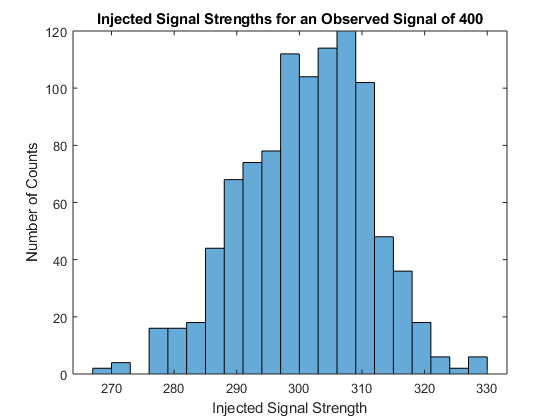

[row, col] = find(abs(injected_data-400)<0.05); 
injected_strengths = row/10000 * 500; 

figure(6)
histogram(injected_strengths); 
xlabel('Injected Signal Strength'); 
ylabel('Number of Counts'); 
title('Injected Signal Strengths for an Observed Signal of 400'); 

**As we can see, our prediction was correct. The suite of injected signal strengths that can produce an injected signal of 400 (with a bound of 0.05) is centered around 300, given that the most likely background signal is 100, and is then spread about this mean value of 300. **

**We can now calculate the 1-sigma uncertainty for the true signal strength given this observed signal of 400. **

true_dist = fitdist(injected_strengths,'Poisson'); 
lowerbound = icdf(true_dist,1-.8413); 
upperbound = icdf(true_dist,.8413); 

bounds = [abs(300-lowerbound) abs(300-upperbound)]; 

sigma_1 = mean(bounds); 
disp("The 1-sigma uncertainty bound on either side of the mean of 300 is " + sigma_1)

The 1-sigma uncertainty bound on either side of the mean of 300 is 17.5


**Given that the upper bound for the 1-sigma uncertainty for the injected signal strength was 317, and the lower bound was 282, yielding 1-sigma ranges of 17 and 18, I would say that this uncertainty interval is definitely symmetric. Unlike the observed signal, this true/injected signal strength is not biased. This is because we expect the injected signals selected above (that produced an observed signal of 400) to match the true signals that also produce the observation of 400. Any variation around the 'truest' signal is then equally biased (above or below), as the background noise distribution is symmetrical about this true value. **

**Problem IV**

**Now instead of selecting an observed signal of 400 (which was ~23 sigma), we now choose a relatively weak observed signal of 110, which falls within a 1 sigma range. As done previously, we want to find the suite of injected signals that can produce this observation. **

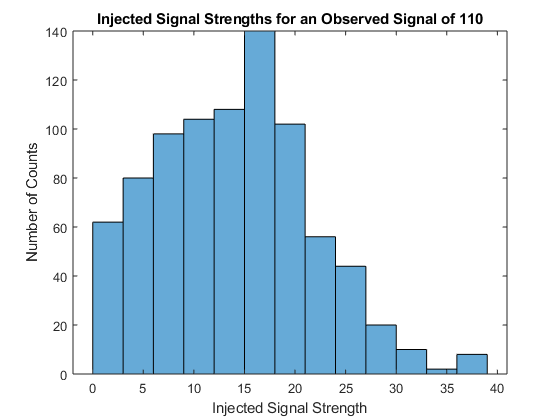

[row, col] = find(abs(injected_data-110)<0.05); 
injected_strengths = row/10000 * 500; 

figure(7) 
histogram(injected_strengths)
xlabel('Injected Signal Strength'); 
ylabel('Number of Counts'); 
title('Injected Signal Strengths for an Observed Signal of 110'); 

**Since the observed signal of 110 is so close to the mean background of 100, we would naturally expect an injected signal of 10 to be the most common, which is confirmed by the histogram. We also see that the plot is roughly symmetrical from injected strengths of 0 - 20, after which it loses its symmetry due to the fact that the injected_signal strength cannot fall below 0. The fact that the distribution drops off to 0 with increasing injected signal strength indicates that after this point, it becomes likely that the background distribution itself will produce this observed signal of 110. **

**We can calculate a 95% confidence interval for this given observed signal, providing an upper bound that the true signal would then fall below 95% of the time. **

true_dist = fitdist(injected_strengths,'Poisson'); 

full = length(injected_strengths); 
integral = 0; 
counts = histcounts(injected_strengths); 

for i = 1:length(counts)
    
    integral = integral + counts(i); 
    if integral/full > 0.95
        break; 
    end
    
end

% compared counts to histogram to get upper bound by inspection
disp("The 95% confidence upper bound is 28"); 

The 95% confidence upper bound is 28


**This means that for the observation of 110, we would expect 95% of all injected signal strengths that could produce this observation to be less than 28. **